# MATLAB and ROS 1

Setup IPs for connecting the Virtual Linux Machine and MATLAB on the laptop

clc
clear 
matlabIP = '192.168.48.1'; % IP address of MATLAB host PC (in a command prompt, 
% do a "ipconfig" and note the Vnet1 address)
rosIP = '192.168.127.130';    % IP address of ROS enabled machine
% (in a Terminal window, do a "ifconfig")

% my info
matlabIP = '172.25.224.1';
rosIP = '172.25.225.224';
%

setenv('ROS_IP',matlabIP); 
setenv('ROS_MASTER_URI',['http://' rosIP ':11311']); 

rosinit(rosIP,11311)

The value of the ROS_IP environment variable, 172.25.224.1, will be used to set the advertised address for the ROS node.
Initializing global node /matlab_global_node_58096 with NodeURI http://172.25.224.1:52849/ and MasterURI http://172.25.225.224:11311.


## Image acquisition

rostopic list

/camera/camera_info                                                   
/camera/image_raw                                                     
/camera/image_raw/compressed                                          
/camera/image_raw/compressed/parameter_descriptions                   
/camera/image_raw/compressed/parameter_updates                        
/camera/image_raw/compressedDepth                                     
/camera/image_raw/compressedDepth/parameter_descriptions              
/camera/image_raw/compressedDepth/parameter_updates                   
/camera/image_raw/theora                                              
/camera/image_raw/theora/parameter_descriptions                       
/camera/image_raw/theora/parameter_updates                            
/camera/parameter_descriptions                                        
/camera/parameter_updates                                             
/clicked_point                                                        
/clock

rostopic info /right_camera/image_raw

Type: sensor_msgs/Image
 
Publishers:
* /gazebo (http://AsusSonia:39975/)
 
Subscribers:
* /rviz (http://AsusSonia:38631/)


sub = rossubscriber('/right_camera/image_raw','DataFormat','struct');
[msg2,status,statustext] = receive(sub,10)

msg2 = struct with fields:
    MessageType: 'sensor_msgs/Image'
         Header: [1×1 struct]
         Height: 0
          Width: 0
       Encoding: ''
    IsBigendian: 0
           Step: 0
           Data: [0×1 uint8]


status = logical
   0


statustext = 'timeout'

% msg2=receive(sub,10);
imageFormatted = rosReadImage(msg2);

Error using rosReadImage
Invalid input message struct. The "rosReadImage" function does not support code generation for empty message struct.

imshow(imageFormatted)

## Image processing

Use of the Color Threshoder MATLAB Apps. Try all color spaces. You will get better results with L*a*b space. It consists of a luminosity 'L*' or brightness layer, chromaticity layer 'a*' indicating where color falls along the red-green axis, and chromaticity layer 'b*' indicating where the color falls along the blue-yellow axis. 

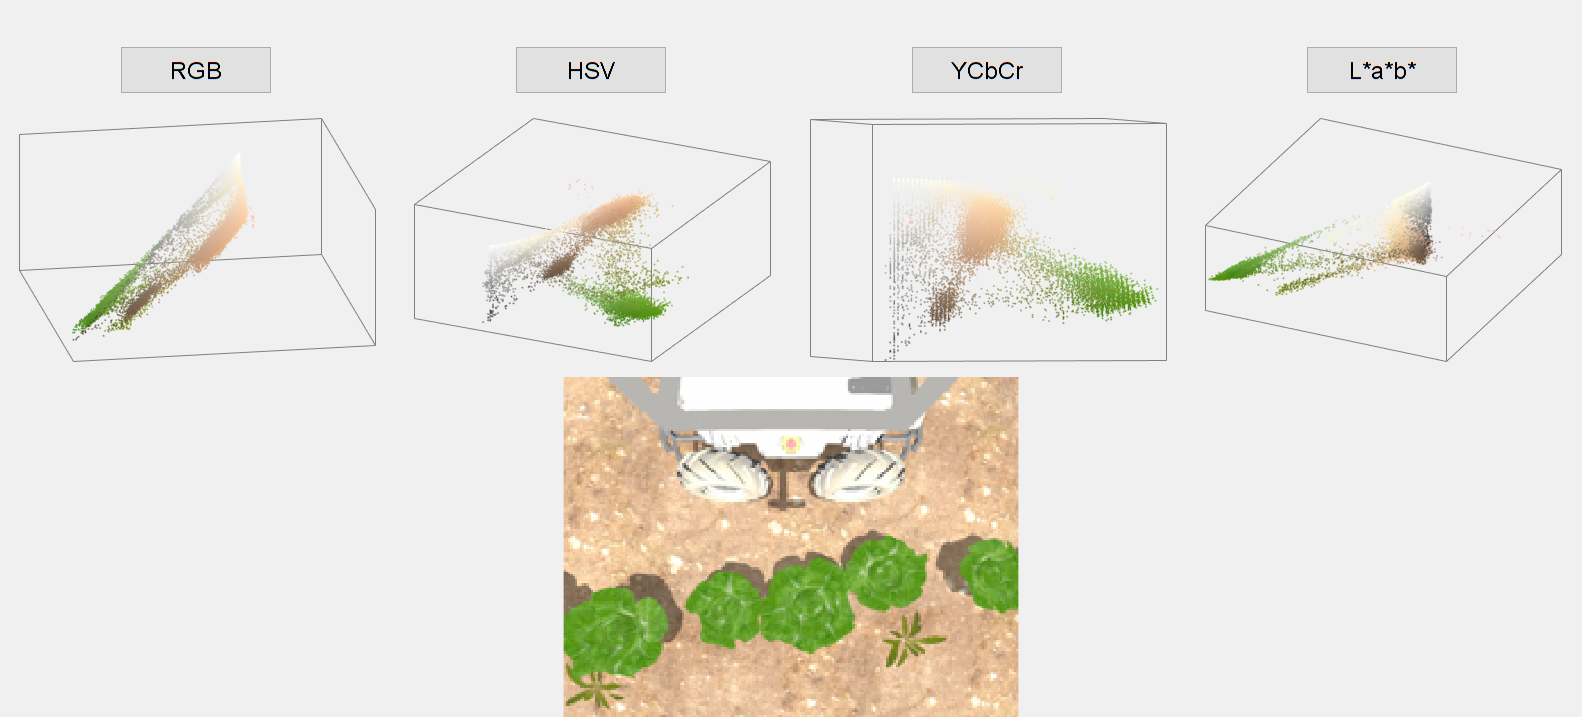

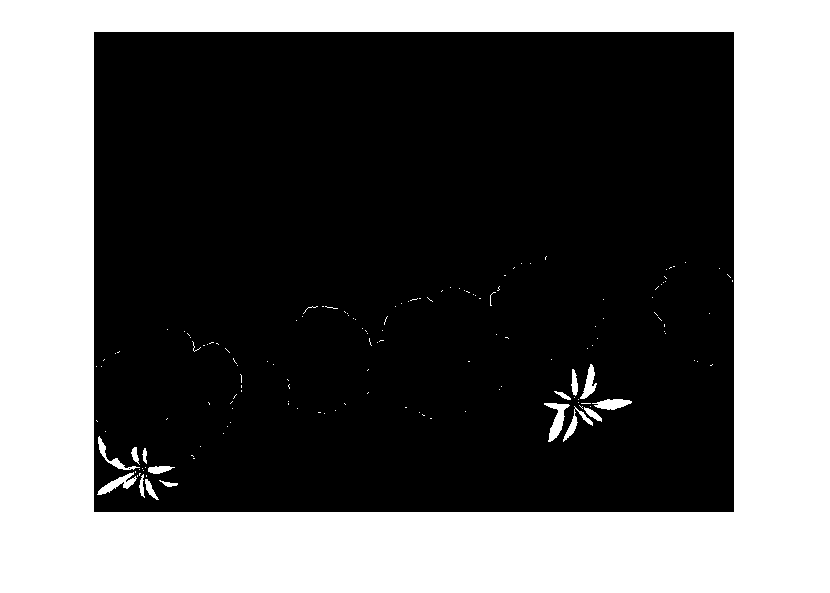

load im1.mat
colorThresholder(imageFormatted)
[BW,maskedRGBImage] = mycreateMask(imageFormatted);
imshow(BW)

## Move Straight

  % Create a publisher which can "talk" to Robot and tell it to move
  pub = rospublisher('/cmd_vel', 'geometry_msgs/Twist');

  % Create a Twist message and add linear x and angular z values
  move_cmd = rosmessage(pub);

  % Set publish rate at 10 Hz
  rate = rosrate(10);

Cannot connect to time source.


  disp("Moving Straight");
  move_cmd.Linear.X =-0.3;           % move in X axis at 0.3 m/s
  move_cmd.Angular.Z = 0.0;

  % For the next 3 seconds publish cmd_vel move commands
  now = rostime('now');
  while rostime('now') - now < rosduration(1)
      send(pub, move_cmd);          % publish to Robot
      waitfor(rate);
  end

## Rotating Counterclockwise

  disp("Rotating");

Rotating


  move_cmd.Linear.X = 0.0;
  move_cmd.Angular.Z = 0.1;         % rotate at 0.2 rad/sec

  % For the next 3 seconds publish cmd_vel move commands
  now = rostime('now');
  while rostime('now') - now < rosduration(3)
      send(pub, move_cmd);          % publish to Robot
      waitfor(rate);
  end

Unrecognized function or variable 'pub'.

## Stop

  disp("Stopping");

Stopping


  move_cmd.Linear.X = 0.0;
  move_cmd.Angular.Z = 0.0;         % Giving both zero will stop the robot

  % For the next 1 seconds publish cmd_vel move commands
  now = rostime('now');
  while rostime('now') - now < rosduration(1)
      send(pub, move_cmd);          % publish to Robot
      waitfor(rate);
  end

Invalid or deleted object.

Error in rateControl/waitfor (line 224)
            currentTime = obj.TimeProvider.getElapsedTime;

  disp("Exit");

## Shutdown ROS node

 rosshutdown;

Shutting down global node /matlab_global_node_58096 with NodeURI http://172.25.224.1:52849/ and MasterURI http://172.25.225.224:11311.
